% Parameterize the arm
rho = 0.03; % M, Radius

%% Construct pose matrices
% Transformations from world frame to each muscle

% Orientation of muscles in world frame:
orntn_muscles = eul2rotm([0, -pi/2, 0], 'xyz');

% Posese of muscle in world frame
% Muscles are arranged in equilateral triangle with radius rho
g_o = SE3(orntn_muscles, [0 0 0]);
g_A = SE3(orntn_muscles, [sqrt(3)/2, -1/2, 0] * rho);
g_B = SE3(orntn_muscles, [-sqrt(3)/2, -1/2, 0] * rho);
g_C = SE3(orntn_muscles, [0, sqrt(3)/2, 0] * rho);

l_0 = 0.1;

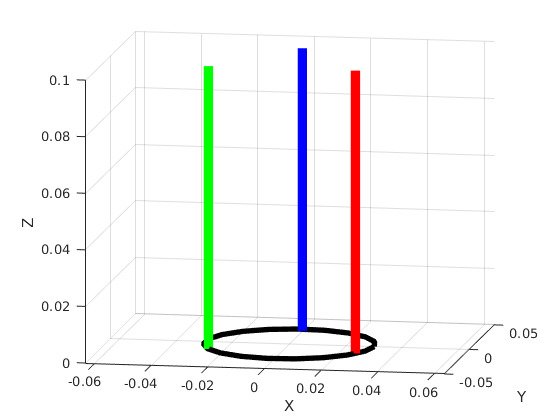

spatial_arm_obj = Arm3D(g_o, {g_A, g_B, g_C}, l_0);

% Configure 3D Arm object
spatial_arm_obj.rho = rho;
spatial_arm_obj.n_circles = 4;

% Initialize plotting
fig = figure();
line_options_muscles = struct("LineWidth", 7);
line_options_circles = struct("LineWidth", 4);
spatial_arm_obj.initialize_plotting(axes(fig), ...
    "line_options_circles", line_options_circles, ...
    "line_options_muscles", line_options_muscles);

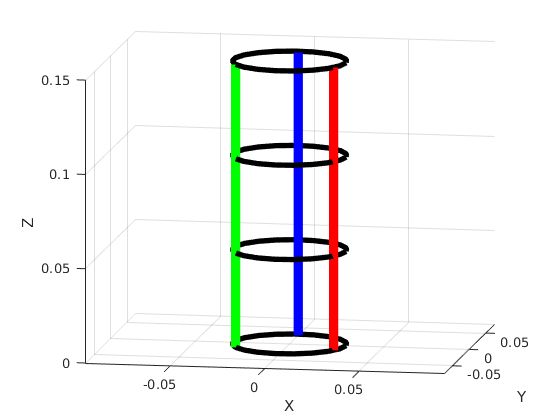

l_A = 0.15;
l_B = 0.15;
l_C = 0.15;
v_l = [l_A; l_B; l_C];

h_o_tilde = spatial_arm_obj.update_arm(v_l);